# Eğri Uydurma ve Aradeğer Hesabı

En Küçük Kareler Metodu ile Eğri Uydurma

## Doğrusal Eğri Uydurma

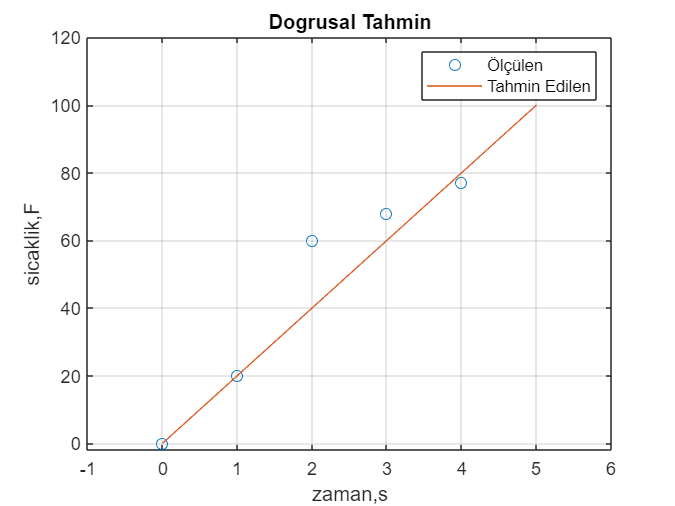

x=0:5;
y=[0,20,60,68,77,110];
yciz=20*x;
hata=yciz-y;
OrtalamaKokHata=sqrt(mean(hata.^2)); % Ortalama karesel hatanın karekökü
%
figure(1)
plot(x,y,'o',x,yciz)
xlabel('zaman,s'),ylabel('sicaklik,F'),title('Dogrusal Tahmin')
grid on
axis([-1,6,-2,120])
legend('Ölçülen','Tahmin Edilen')

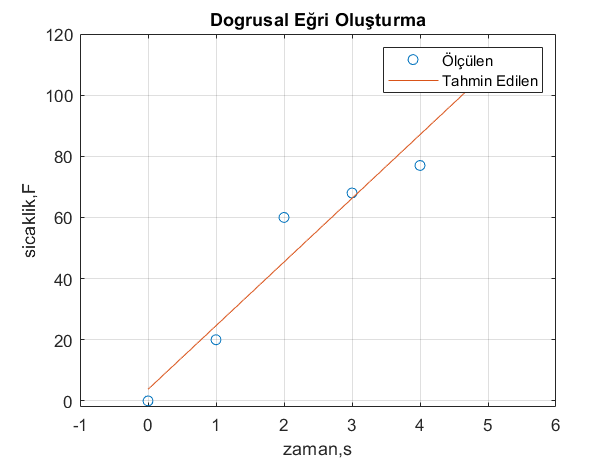

%
x=0:5;
y=[0,20,60,68,77,110];
a=polyfit(x,y,1);
yciz=polyval(a,x);
hata=yciz-y;
OrtalamaKokHata=sqrt(mean(hata.^2));
figure(2)
plot(x,y,'o',x,yciz)
xlabel('zaman,s'),ylabel('sicaklik,F'),title('Dogrusal Eğri Oluşturma')
grid on
axis([-1,6,-2,120])
legend('Ölçülen','Tahmin Edilen')

## Doğrusal Olmayan Eğri Uydurma (polinom tipi)

figure(3)

x=0:0.1:1;
y=[-0.447 1.978 3.28 6.16 7.08 7.34 7.66 9.56 9.46 9.30 11.2];
a2=polyfit(x,y,2)

a2 =    -9.8085   20.1215   -0.0304


disp('a2 katsayilari:')

a2 katsayilari:


disp(a2')

  -9.8085e+00
   2.0122e+01
  -3.0413e-02



a10=polyfit(x,y,10);
disp('a10 katsayilari:')

a10 katsayilari:


format short e
disp(a10')

  -4.6684e+05
   2.3081e+06
  -4.9007e+06
   5.8496e+06
  -4.3129e+06
   2.0290e+06
  -6.0538e+05
   1.0931e+05
  -1.0658e+04
   4.3712e+02
  -4.4700e-01



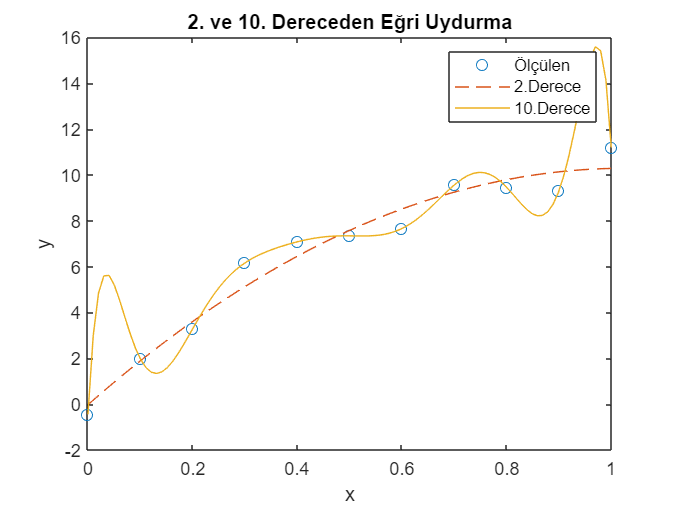

xi=linspace(0,1,100);
yi2=polyval(a2,xi);
yi10=polyval(a10,xi);
plot(x,y,'o',xi,yi2,'--',xi,yi10)
xlabel('x'),ylabel('y')
title('2. ve 10. Dereceden Eğri Uydurma')
legend('Ölçülen','2.Derece','10.Derece')